ODE Homework

Kathryn Atherton

ABE 30100 

03/25/2019

TAOCO is making a new pharmaceutical biologic product (WOWEE) by enzymatic modification of a recombinant protein (A) in a well-mixed tank reaction system (see diagram below).   As a business, TAOCO is interested in process performance, which can be evaluated by production of WOWEE, efficient conversion of A, time needed to start-up the process, and the amount of waste produced.

Starting up the process involves getting the system to steady state from initial conditions (i.e. accumulation is not zero during start-up).  At the start-up of this process, the reactor is initially filled with fluid at Ain.  At time =0, the inlet/outlet flows are started and the reaction begins.  

Note: This process asymptotically approaches steady state operation.

Assume that the mixing in the tank is perfect, i.e. entering materials are instantaneously mixed and the composition is spatially uniform inside of the tank.  Assume that concentration leaving the tank is the same as the concentration inside of the tank and that the flowrates and volume of fluid in the tank is constant.

V – tank volume (L)

F – volumetric flowrate (L/hr)

Ain – feed concentration of protein (mol/L)

A(t) – protein concentration in tank/outlet (mol/L) 

r – reaction rate, dC/dt (mol/L-hr)

Vm, Km – enzymatic reaction rate constants (mol/L-hr, mol/L)

Part A

(10 points) Using the parameter values below, **develop a numerical model/solution for this process** and **provide an appropriate plot of the protein concentration as a function of time** during the start-up process (0<t<100), i.e. solve for A(t).

V = 500; % [L]
F = 100; % [L/hr]
Ain = 100; % [mol/L]
Vm = 10; % [mol/L-hr]
Km = 5; % [mol/L]

syms At t
r = -Vm * At / (Km + At); % [mol/L-hr]
in = Ain * F / V; % [mol/hr]
out = At * F / V; % [mol/hr]
dAt_dt = in - out + r; % [mol/hr]

i = 1

i = 1

time = 0:0.1:100;
At_solve = zeros(length(time),1);

At_solve(i) = Ain;
while i < length(time)
    i = i + 1;
    slope = subs(dAt_dt, At, At_solve(i-1));
    At_solve(i) = At_solve(i-1) + slope * 0.1; 
end
At_solve(i)

ans = 54.2214

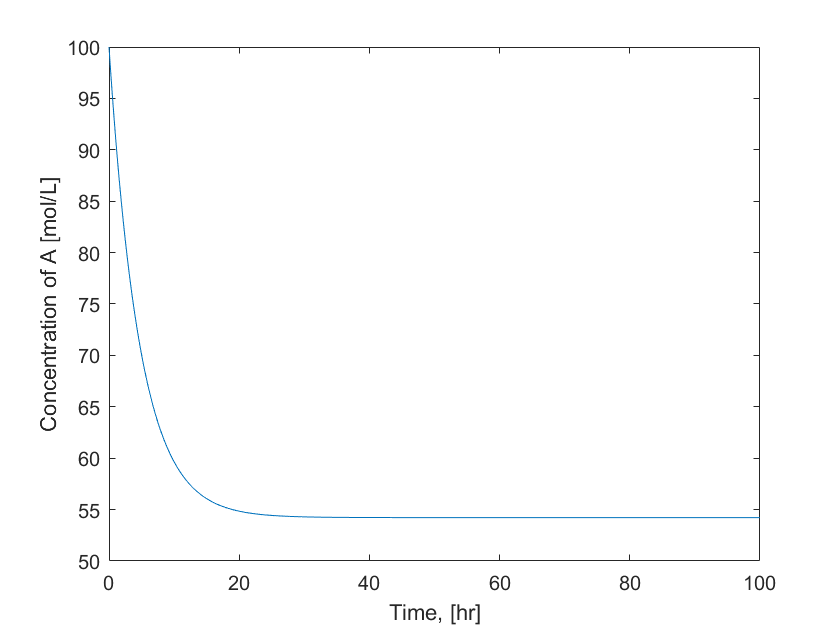

plot(time, At_solve)
xlabel('Time, [hr]')
ylabel('Concentration of A [mol/L]')

Part B

(2 point) Assume that the value of the protein concentration at t=100 is the asymptotic steady state value.  **Provide an appropriate plot of the % conversion vs. time** (0<t<100).

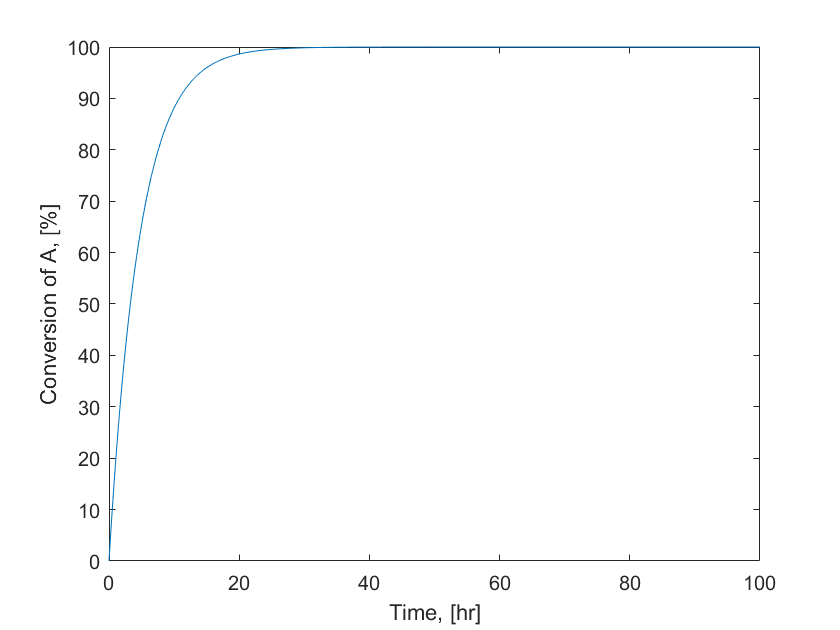

conversion = (At_solve(1) - At_solve) ./ (At_solve(1) - At_solve(1001)) * 100;
plot(time,conversion)
xlabel('Time, [hr]')
ylabel('Conversion of A, [%]')

Part C

(2 point) During start-up, assume that product collection can begin when the conversion reaches 99% of the asymptotic steady state value.  Using your model, **calculate the start-up time (hr),** i.e. the time until product can first be collected.  

i = 1;
while conversion(i) < 99
    i = i + 1; 
end
collect = time(i)

collect = 21.5000

Part D

(2 points) **Calculate the amount of waste** **(mol) **generated during start-up.  (Waste is all the moles of material used/produced before collection starts.)

% Assuming Reaction is A -> B (Wowee product)
syms Bt
in_b = 0;
out_b = Bt * F / V;
gen = -1 * r; 
dBt_dt = in - out + gen; 

i = 1

i = 1

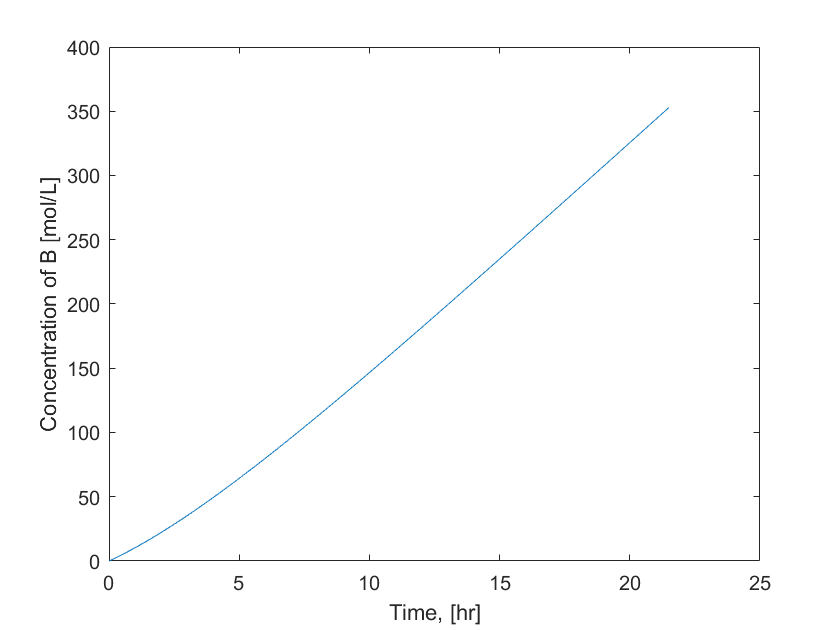

time = 0:0.1:collect;
Bt_solve = zeros(length(time),1);

Bt_solve(i) = 0;
while i < length(time)
    i = i + 1;
    slope = subs(dBt_dt, Bt, Bt_solve(i-1));
    slope = subs(slope, At, At_solve(i-1));
    Bt_solve(i) = Bt_solve(i-1) + slope * 0.1; 
end
plot(time, Bt_solve)
xlabel('Time, [hr]')
ylabel('Concentration of B [mol/L]')


waste = trapz(Bt_solve) * V

waste = 1.7676e+07